% III


% hbar = 1.0545718e-34; 
% mass_He = 6.6464764e-27; 
% lambda_dB = 45e-12; 
% k_dB = 2 * pi / lambda_dB; 
% d = 6.55e-6; 
% w_slit = 0.6e-6; 
% R_source = 1.27;
% open_fraction = 0.1; 
% z_max = 2; 
% L_x = 2*d; 
% N = 1024; 
% x = linspace(-L_x/2, L_x/2, N); 
% dx = x(2) - x(1); 
% dk = 2 * pi / (N * dx); 
% k_x = (-N/2:N/2-1) * dk;
% k_x= fftshift(k_x);
% vel= (2*pi*hbar/lambda_dB)/mass_He
% L_T = 2*d^2 / lambda_dB; 
% disp(['Calculated Talbot Length: ', num2str(L_T), ' meters']);

% grating = (mod(x, d) < open_fraction * d);
% 
% grating = grating / sqrt(sum(abs(grating).^2)*dx);
% 
% psi_0 = grating;
% 
% psi_0 = psi_0 / sqrt(sum(abs(psi_0).^2) * dx);
% 
% psi_k_0 = fft(psi_0);
% 
% z = linspace(0, z_max, 200); 
% psi_x_z = zeros(N, length(z)); 
% 
% for j = 1:length(z)
% 
%     psi_k_z = psi_k_0 .* exp(-1i * (hbar * k_x.^2 * z(j)/vel) / (2 * mass_He));
% 
% 
%     psi_x_z(:, j) = ifft(psi_k_z);
% 
% 
%     psi_x_z(:, j) = psi_x_z(:, j) / sqrt(sum(abs(psi_x_z(:, j)).^2) * dx);
% end
% 
% figure;
% imagesc(z, x * 1e6, abs(psi_x_z).^2); 
% xlabel('z (m)');
% ylabel('x (\mum)');
% title('Talbot Carpet for Plane Wave Input');
% colormap('default');
% colorbar;




clear

hbar = [1.044e-34,1]; 

N = 2^16;

xmax = 8e-3;        

dx = xmax/N;

n = 0:1:(N-1); p = n;

xn = -xmax/2 + n*dx;


pmax = 2*pi*hbar(1)/dx;

dp = 2*pi*hbar(1)/xmax;

pn = -pmax/2 + p.*dp;

z_sa = 1.27;                   
z_ad = 2;                      
source_slit = 2e-6;             
detector_size = 30e-6;          
lam_dB = 0.45e-10;             
m_n = 1.675e-27;                
d = 6.55e-6;                     
diffract_slit = 0.65e-6;        
fill_factor = 10;
L_t = 2*(d^2)/lam_dB;          
L_te = 2*(1 + z_ad/z_sa)*d^2/lam_dB;
disp(['Calculated Talbot Length: ', num2str(L_t), ' meters']);

Calculated Talbot Length: 1.9068 meters


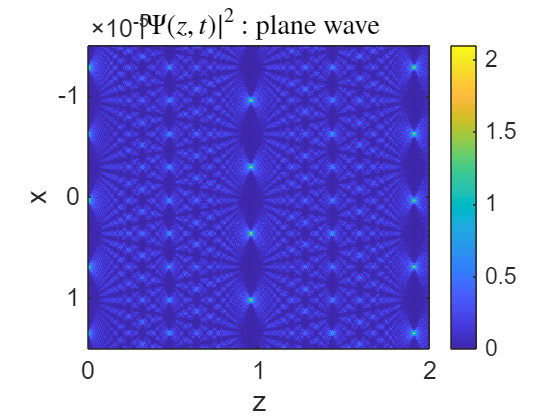

m_He = 2*m_n;

Nz = 5000;
zend = z_ad;

dz = zend/Nz;
z = 0:dz:zend;

v = 2*pi*hbar(1)/m_He/lam_dB;        

dt = dz/v;

%dU = exp(-1i*pn.^2.*dt./2./m_n./hbar(1));
U = dU(dt,pn,m_He,hbar(1));

N_half = (xmax/2)./d;

N_frac = N_half - floor(N_half);

shift = (d/2) - d.*N_frac;

x_grating = (2*pi/d).*xn;


gv = 0.5.*square(x_grating,fill_factor) + 0.5;
% figure;
% plot(xn, gv);
% ylim([0,1.1]);

psi0_pw = gv;      
% figure;
% plot(xn,psi0_pw);
psi0_pw_p = ftxtop(psi0_pw,dx,hbar(1));
% figure;
% plot(pn,psi0_pw_p);
Psi0_pw_p = zeros(length(z),length(psi0_pw_p));
Psi0_pw_x = zeros(length(z),length(psi0_pw_p));
for zi = 1:length(z)
    dt = z(zi)./v;
    Psi0_pw_p(zi,:) = dU(dt,pn,m_He,hbar(1)).*psi0_pw_p;
    Psi0_pw_x(zi,:) = iftptox(Psi0_pw_p(zi,:),dp,hbar(1));
end

ap = (xn >= -detector_size/2 & xn <= detector_size/2);
x_limited = xn(ap);


% figure;
% imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0_pw_x').^2);
imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0_pw_x(:,ap)').^2);
set(gca,'FontSize',15);
xlabel('z');
ylabel('x');
title('$|\Psi(z,t)|^2$ : plane wave',Interpreter='latex');
colormap parula;
colorbar;

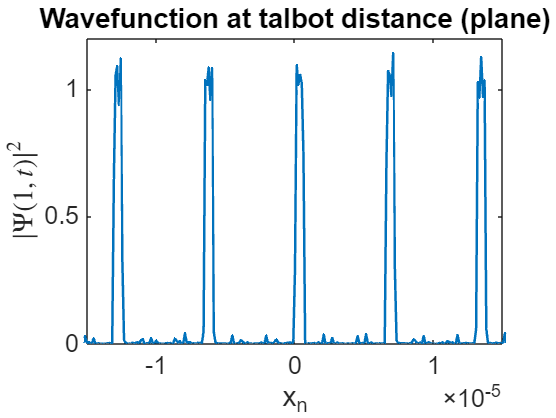



figure;
plot(xn,abs(Psi0_pw_x(4768,:)).^2,'LineWidth',1.5);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title('Wavefunction at talbot distance (plane)');
set(gca,'FontSize',15);
xlim([-detector_size/2,detector_size/2]);

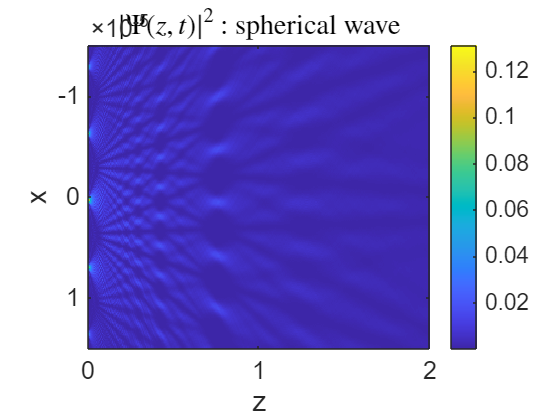


slit = gv;

dt = z_sa/v;

psi0source = rect(xn,source_slit);
psi0spherical = slit.*iftptox(dU(dt,pn,m_He,hbar(1)).*ftxtop(psi0source,dx,hbar(1)),dp,hbar(1));

psi0spherical_p = ftxtop(psi0spherical,dx,hbar(1));
Psi0spherical_p = zeros(length(z),length(psi0spherical_p));
Psi0spherical_x = zeros(length(z),length(psi0spherical_p));
for zi = 1:length(z)
    dt = z(zi)./v;
    Psi0spherical_p(zi,:) = dU(dt,pn,m_He,hbar(1)).*psi0spherical_p;
    Psi0spherical_x(zi,:) = iftptox(Psi0spherical_p(zi,:),dp,hbar(1));
end

ap = (xn >= -detector_size/2 & xn <= detector_size/2);
x_limited = xn(ap);
figure;
imagesc([0,z_ad],[-detector_size/2, detector_size/2],abs(Psi0spherical_x(:,ap)').^2);
set(gca,'FontSize',15);
xlabel('z');
ylabel('x');
title('$|\Psi(z,t)|^2$ : spherical wave',Interpreter='latex');
colormap parula;
colorbar;

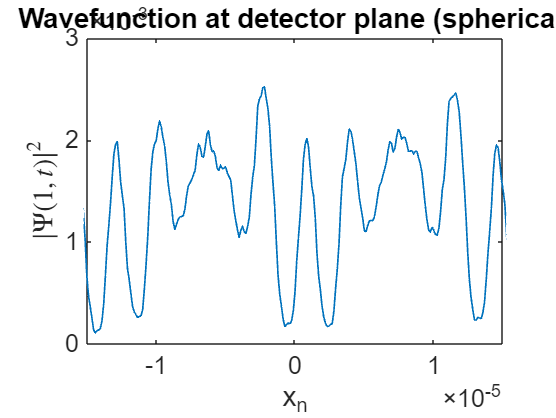



figure;
plot(xn,abs(Psi0spherical_x(end,:)).^2,'LineWidth',1);
xlabel('x_n');
ylabel('$|\Psi(1,t)|^2$',Interpreter='latex');
title('Wavefunction at detector plane (spherical)');
xlim([-detector_size/2,detector_size/2]);
set(gca,'FontSize',15);


function [U] = dU(dt,p,m,hbar)
    U = exp(-1i.*(p.^2).*dt./2./m./hbar);
end

function y = rect(t,bound)
    y = abs(t) <= bound/2;
    y = double(y);  
end

function [fp] = ftxtop(fx,dx,hbar)
    N  = length(fx);
    fp = dx*(1/2/pi/hbar)^(1/2)*fftshift(fft(ifftshift(fx)));
end

function [fx] = iftptox(fp,dp,hbar)
    N  = length(fp);
    fx = (N)*dp*(1/2/pi/hbar)^(1/2)*ifftshift(ifft(fftshift(fp)));
end